# 5.9. Интерференция

#### Интерференция двух когерентых волн

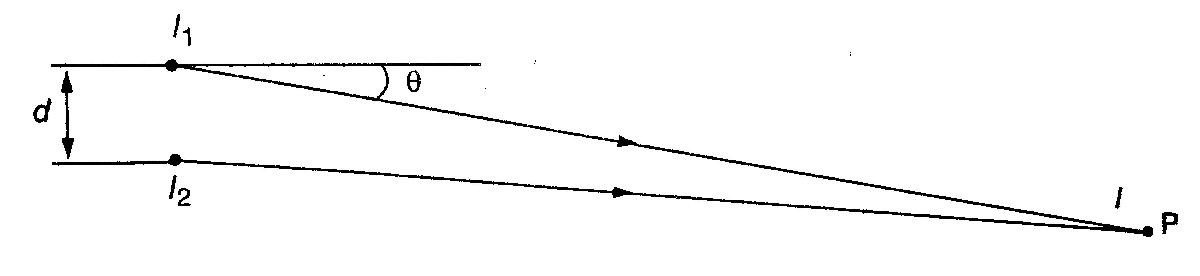

clear
syms I I1 I2 delta
I==I1+I2+2*sqrt(I1*I2)*cos(delta)

$$ans = \text{I}=I_{1}+I_{2}+2\,\cos\left(\delta \right)\,\sqrt{I_{1}\,I_{2}}$$

Разность фаз в точке интерференции P

syms delta lambda d theta
delta==2*pi/lambda*d*sin(theta)

$$ans = \delta =\frac{2\,\pi \,d\,\sin\left(\theta \right)}{\lambda }$$

#### Интерференция N когерентных волн

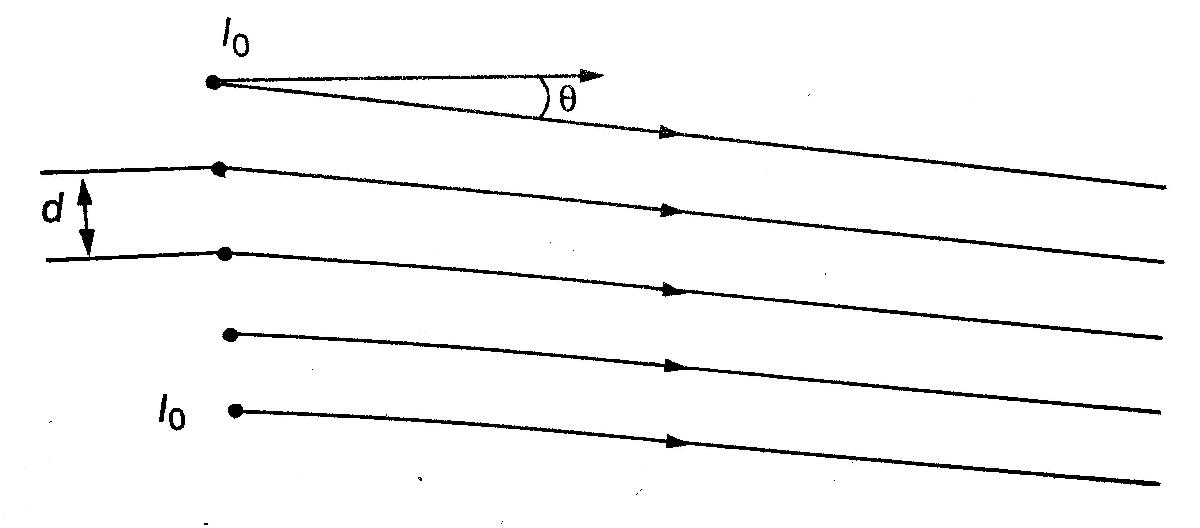

syms I I0 N delta 
I==I0*(sin(N*delta/2)/sin(delta/2))^2, delta==2*pi/lambda*d*sin(theta)

$$ans = \text{I}=\frac{I_{0}\,{\sin\left(\frac{N\,\delta }{2}\right)}^{2}}{{\sin\left(\frac{\delta }{2}\right)}^{2}}$$

$$ans = \delta =\frac{2\,\pi \,d\,\sin\left(\theta \right)}{\lambda }$$

Главные максимумы

syms m
d*sin(theta)==m*lambda   % m=0,+-1,+-2,...

$$ans = d\,\sin\left(\theta \right)=\lambda \,m$$

Минимумы

syms m1
N*d*sin(theta)==m1*lambda    % m1 целый числа, m1=+-0,+-N,+-2N,...

$$ans = N\,d\,\sin\left(\theta \right)=\lambda \,m_{1}$$

#### Интерференция при отражении от тонких пленок

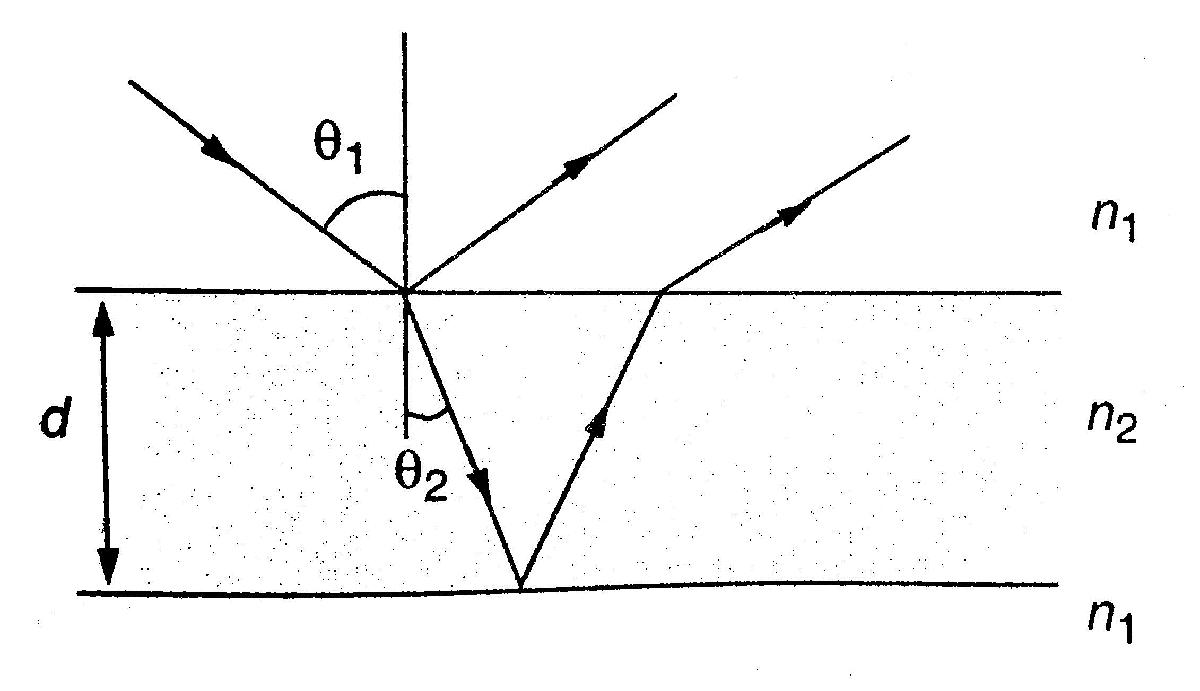

Сдвиг фазы двух лучей

syms delta lambda d n2 theta2 
delta==2*pi/lambda*2*d*n2*cos(theta2)+pi

$$ans = \delta =\pi +\frac{4\,\pi \,d\,n_{2}\,\cos\left(\theta_{2}\right)}{\lambda }$$

#### Условие минимума для колец Ньютона

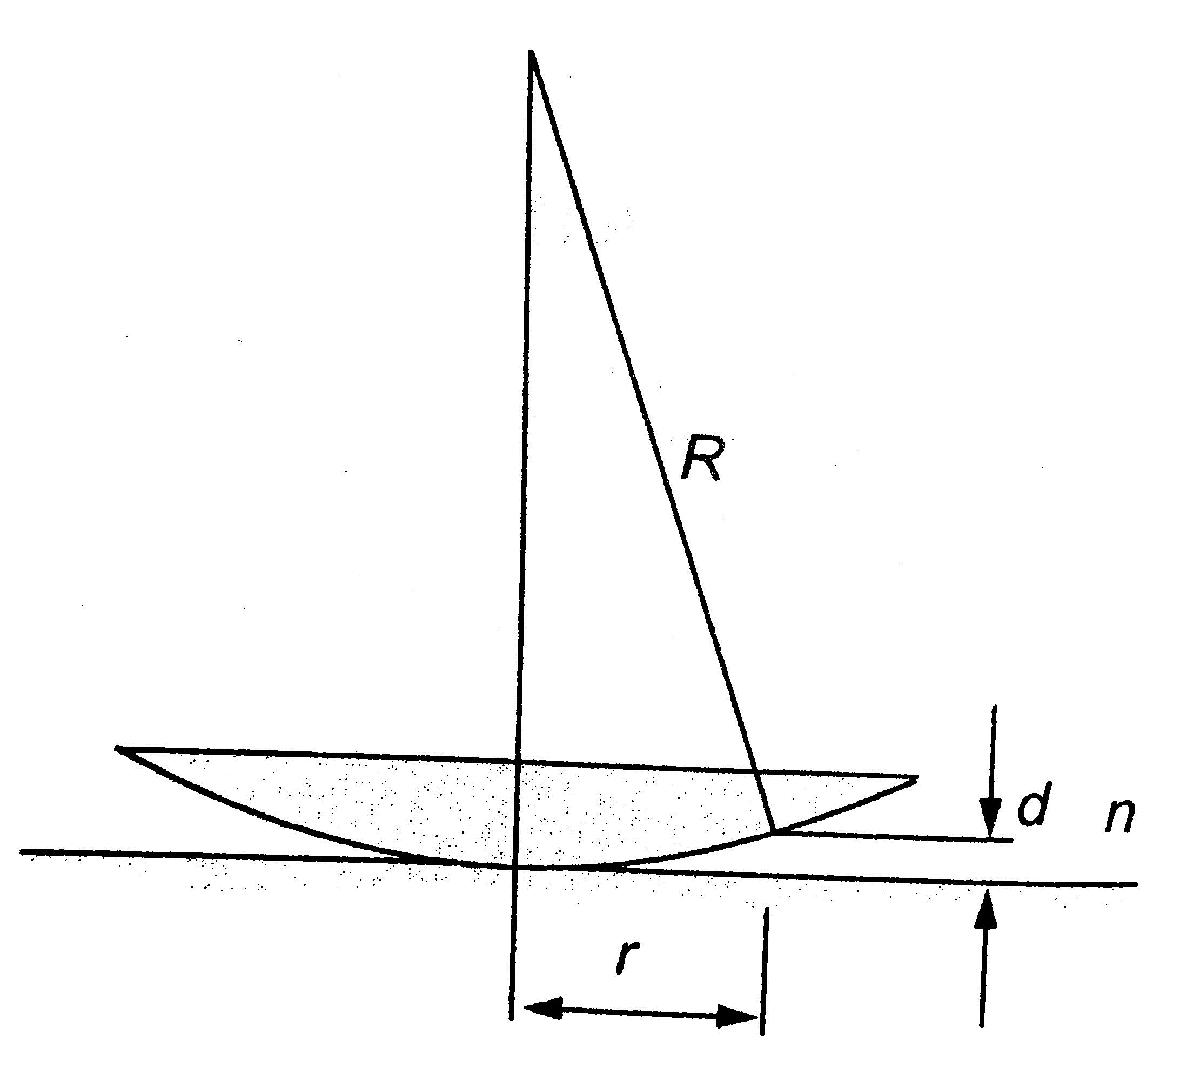

syms n d m lambda R r 
2*n*d==m*lambda

$$ans = 2\,d\,n=\lambda \,m$$

r^2*n==m*R*lambda  % m=0,1,2,...

$$ans = n\,r^{2}=R\,\lambda \,m$$

#### Интерферометр Фабри-Перо

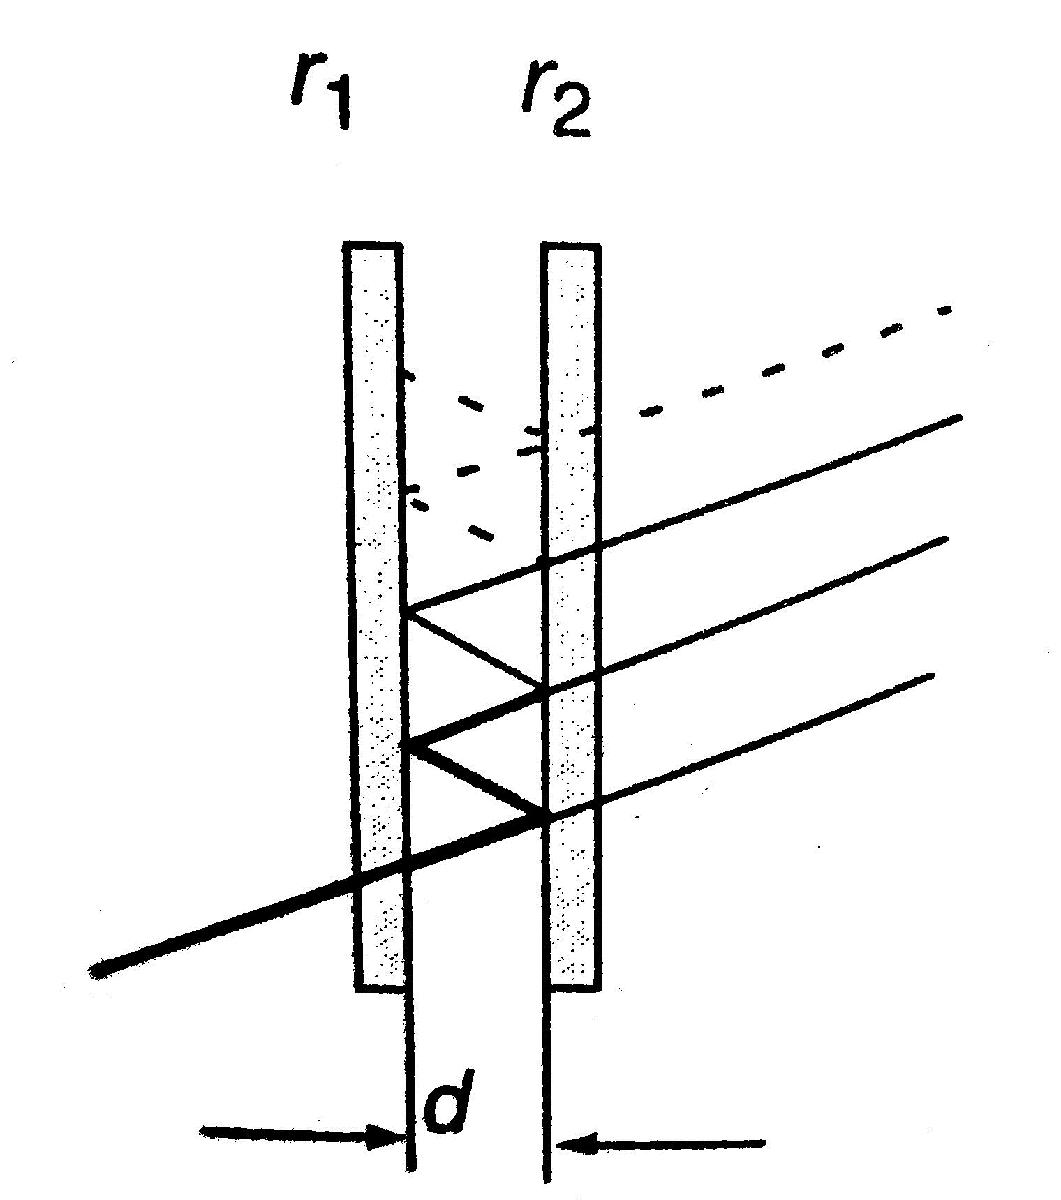

Спектральный интервал

syms Delta(x) nu_FSR c0 n d
% FSR - Free Spectral Range
Delta(nu_FSR)==c0/(2*n*d)     % плоские зеркала

$$ans = \Delta \left(\nu_{\mathrm{FSR}}\right)=\frac{c_{0}}{2\,d\,n}$$

Delta(nu_FSR)==c0/(4*n*d)     % конфокальные зеркала

$$ans = \Delta \left(\nu_{\mathrm{FSR}}\right)=\frac{c_{0}}{4\,d\,n}$$

Разрешающая способность

syms R lambda nu m r1 r2 
R==lambda/abs(Delta(lambda))==nu/abs(Delta(nu))== ... 
    m*pi*(r1*r2)^(1/4)/(1-sqrt(r1*r2)), m==2*d/lambda

$$ans = \left(\left(R=\frac{\lambda }{\left|\Delta \left(\lambda \right)\right|}\right)=\frac{\nu }{\left|\Delta \left(\nu \right)\right|}\right)=-\frac{\pi \,m\,{\left(r_{1}\,r_{2}\right)}^{1/4}}{\sqrt{r_{1}\,r_{2}}-1}$$

$$ans = m=\frac{2\,d}{\lambda }$$

% r_i = коэффициент отражения
% Тонкость =
Delta(nu_FSR)/Delta(nu)

$$ans = \frac{\Delta \left(\nu_{\mathrm{FSR}}\right)}{\Delta \left(\nu \right)}$$

#### Видность

syms V I_max I_min
V==(I_max-I_min)/(I_max+I_min)

$$ans = V=-\frac{I_{\min}-I_{\max}}{I_{\min}+I_{\max}}$$

#### Время и длина когерентности

syms tau L c0 
tau==1/Delta(nu)

$$ans = \tau =\frac{1}{\Delta \left(\nu \right)}$$

L==c0*tau==lambda^2/Delta(lambda)

$$ans = \left(L=c_{0}\,\tau \right)=\frac{\lambda^{2}}{\Delta \left(\lambda \right)}$$

Delta(nu), Delta(lambda) % = ширины частоты и длины волны волновых пакетов

$$ans = \Delta \left(\nu \right)$$

$$ans = \Delta \left(\lambda \right)$$